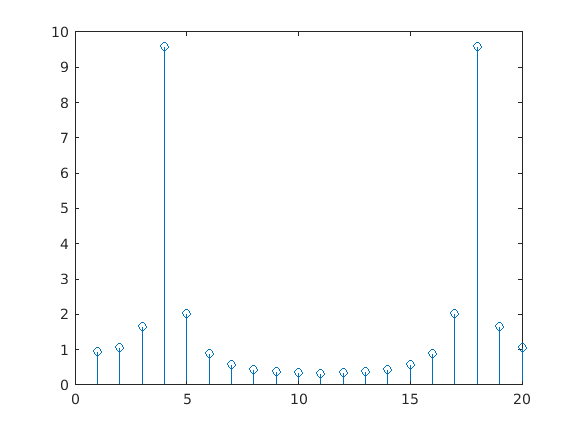

clear
clearvars
load('evenfaster.mat')
time = Acceleration.Timestamp.Second;
amp = Acceleration.Z;

N = length(time);
%amp = sin([0:N-1]);

transform = abs(fft(amp));
frequencies = linspace(-pi, pi-2*pi/N, N) + pi/N*mod(N,2);




step_size = 20; %number of points to include in each fft
num_steps = ceil(N/step_size);
for i = 1:num_steps
    data_seg = [];
    range = (step_size*(i-1)+1):(step_size*i);
    for k = 1:N
        if ismember(k, range)
            k_remapped = k - step_size*(i-1);
            data_seg(k_remapped) = amp(k);
        end
    end
    transform = abs(fft(data_seg));
    if i == 10
        stem(transform)
    end
    freq(i) = mean(transform);
end

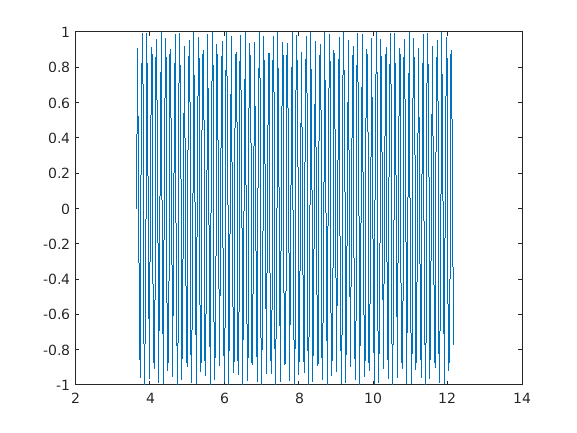


plot(time, amp)

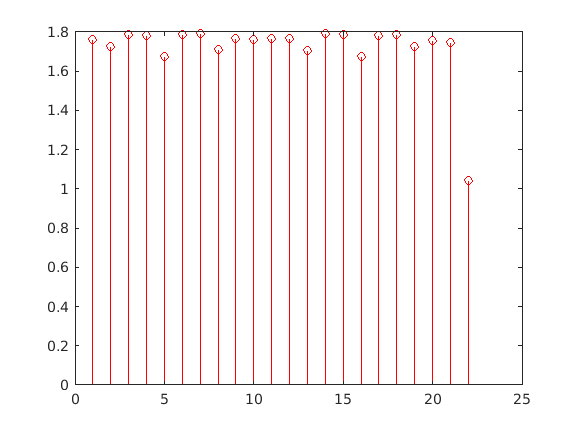

%plot([1:num_steps], freq, 'r')
stem(freq, 'r')